Problem 1.1

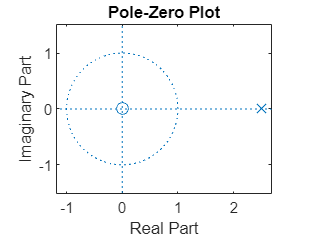

syms y(n) z R0  % define system and variables
assume(n>=0 & in(n,"integer"))
f = y(n) - R0*y(n-1) - kroneckerDelta(n); % define eqn
fZT = ztrans(f,n,z); % take z transform
syms yZT
fZT = subs(fZT,ztrans(y(n),n,z),yZT); % substitute yzt transform in terms of ztransform
yZT = solve(fZT,yZT); % write in terms of Z
ySolz = subs(yZT,[y(-1)], [0]);
r0 = 2.5;
b = -1;
a = [-1, r0];
zplane(b,a) % Pole zero plot

Problem 1.2

ySol = iztrans(yZT,z,n); % take inverse z transform
ySol = simplify(ySol); % simplify
ySol = subs(ySol,[y(-1)],[0]) % put intial conditions

$$ySol = \left\{ \begin{array}{cl} \delta_{n,0} & \text{ if }R_{0}=0\\ {R_{0}}^{n} & \text{ if }R_{0}\neq 0 \end{array}\right.$$

Problem 1.3


ySol1 = subs(ySol,[y(-1) R0],[0 2.5]) % put intial conditions

$$ySol1 = {\left(\frac{5}{2}\right)}^{n}$$

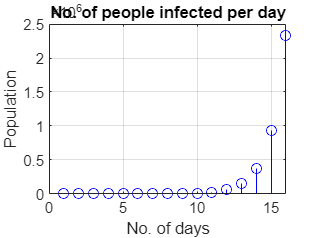

nValues = 1:16;
ySolValues = subs(ySol1,n,nValues);
ySolValues = double(ySolValues);
ySolValues = real(ySolValues);
stem(nValues, ySolValues,"b")
title("No. of people infected per day")
ylabel("Population")
xlabel("No. of days")
grid on

figure;
ySolValues(15)

ans = 9.3132e+05

ySolValues(16)

ans = 2.3283e+06

% ansr is 16 days

Problem 1.4

syms y(n) z R0(n)  % define system and variables
assume(n>=0 & in(n,"integer"))
f1 = y(n) - R0(n)*y(n-1) - kroneckerDelta(n) % define eqn

$$f1 = y\left(n\right)-y\left(n-1\right)\,R_{0}\left(n\right)-\delta_{n,0}$$

days = 50;
syms r
f1 =  subs(f1,R0(n),r); 
r = solve(f1,r);
Y = [2, 4, 5, 6, 10, 19, 65, 78, 114, 137, 140, 144, 173, 204, 225, 245, 254, 287, 307, 341, 368, 373,387, 404, 423, 460, 506, 571, 596, 614, 658, 688, 755, 807, 835, 855, 1007, 1143, 1245, 1391,1607, 1806, 1907, 2111, 2191, 2340, 2528, 2710, 2772, 2865] ;% find data for first 50 days frm covid website
rT = zeros(1,days); % put days here
for i =1:length(Y)-1
    r1 = subs(r,n,i);
    rT(i) = subs(r1,[y(i-1) y(i)],[Y(i) Y(i+1)]);
end
R_avg = sum(rT)/length(rT)

R_avg = 1.1700

Problem 1.5

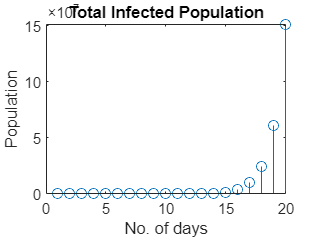

% intergrator filter
b1 = 1;
a1 = [1 -1];
nValues = 1:20;
ySolValues = subs(ySol1,n,nValues);
ySolValues = double(ySolValues);
ySolValues = real(ySolValues); % data for 1st 20 days
I = filter(b1,a1,ySolValues); % intergrator filter
stem(I)
title("Total Infected Population")
ylabel("Population")
xlabel("No. of days")

figure;
Total_infected_people = I(20)

Total_infected_people = 1.5158e+08